# Page Rank

## Create the page ranking model

This code is based entirely on the course book Matrix Methods in Data Mining and Pattern Recognition (2nd Edition), Lars Eldén.

clear

% Open the file for reading
fileID = fopen('Data/data-course-book-1.txt', 'r');

% Read the file line by line
data = textscan(fileID, '%s', 'Delimiter', '\n');
data = data{1};

% Close the file
fclose(fileID);

% Extract all information from the .txt file
[nodes, edges] = extractNodesAndEdges(data);

nodeKeys = nodes.keys;
numNodes = numel(nodeKeys);

% Generate a sparse matrix, Q, representing node connectivity.
% Rows indicate if a node has incoming links,
% while columns indicate outgoing links.
% It also creates a vector, d, that identifies nodes as dead ends in the network.
[Q, d] = createSparseMatrix(edges, numNodes);

full(Q)

ans =          0    0.3333         0         0         0         0
    0.3333         0         0         0         0         0
         0    0.3333         0         0    0.3333    0.5000
    0.3333         0         0         0    0.3333         0
    0.3333    0.3333         0         0         0    0.5000
         0         0    1.0000         0    0.3333         0


## Optional modelling

This part is only used for eigen-solution and Power Method without optimization.

% If a node has a dead end, adjust the matrix to redirect the user to any
% other page
e = ones(numNodes, 1);
P = Q + (e * d') / numNodes

P =          0    0.3333         0    0.1667         0         0
    0.3333         0         0    0.1667         0         0
         0    0.3333         0    0.1667    0.3333    0.5000
    0.3333         0         0    0.1667    0.3333         0
    0.3333    0.3333         0    0.1667         0    0.5000
         0         0    1.0000    0.1667    0.3333         0


alpha = 0.85;
v = e / numNodes;

% This is the final adjustment of the matrix. It accounts
% for a user's action when clicking to a new page or manually typing
% in a new website. The probability of clicking to a new page based on
% the current site is 85% (alpha), while the chance of manually typing
% in a new site is 15% (1 - alpha), this is for prevents the system from
% becoming stuck within subgraphs
A = alpha * P + (1 - alpha) * v * e';

## Solve using eigenvalues and eigenvectors

This can be used for smaller matrices, but is not suitable for large matrices (take a lot of time)  

[R, L] = eig(A);

Unrecognized function or variable 'A'.


R % Eigenvectors (col), choose the one with eigenvalue 1 
diag(L) % Eigenvalues
rank = R(:, 1) % Choses col 1 because it has the eigenvalue 1
rank = rank / norm(rank, 1) % Normalize to get the probability 
% Debug 
sum(rank) % Sum should be 1 - data-course-book-2 is -1! FIX!

## Solve using Power Method

This can be used for large matrices 

% Initial rank for every page, starts with random probability
rank = rand(numNodes, 1);
rank = rank / norm(rank, 1);

% Set convergence threshold
threshold = 1e-6; % 1e^-4 / 1e^-6 
prevRank = rank; % Store the previous rank for comparison

% Iterate the ranks until convergence
maxIterations = 10000;
for i = 1 : maxIterations
    rank = A * prevRank;

    % Check for convergence
    if norm(rank - prevRank) < threshold
        disp(['Converged at iteration ', num2str(i)]);
        break; % Stop the loop if converged
    end

    prevRank = rank; % Update the previous rank
end

Converged at iteration 52


## Optimizing the Power Method 

% Initialization
z = rand(numNodes, 1);
z = z / norm(z, 1);
threshold = 1e-6; % 1e^-4 / 1e^-6 
maxIterations = 10000;

for i = 1 : maxIterations
    yhat = alpha * Q * z;
    beta = 1 - norm(yhat, 1);
    y = yhat + beta * v;
    residual = norm(y - z, 1);

    if residual < threshold
        disp(['Converged at iteration ', num2str(i)]);
        break; % Stop the loop if converged
    end

    z = y; % Update z for the next iteration
end

Converged at iteration 21


rank = z;

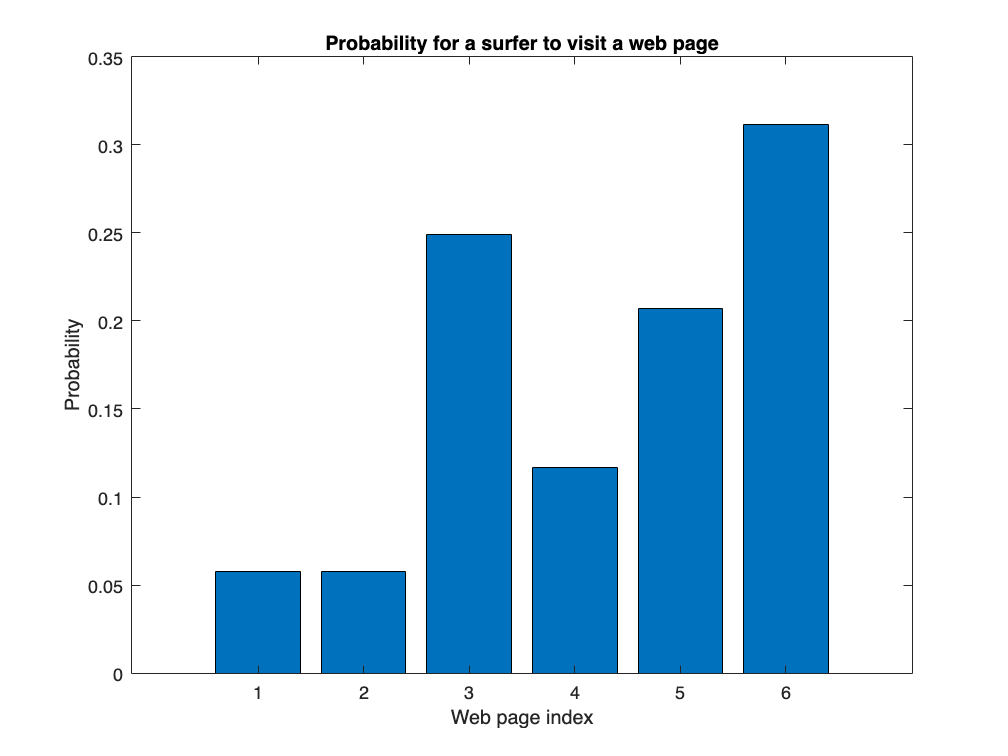

%Plot the result 
bar(rank)
title('Probability for a surfer to visit a web page')
xlabel('Web page index')
ylabel('Probability')

min(rank)

ans = 0.0579


% Sort the page ranks and get the indices
[sortedRanks, indices] = sort(rank, 'descend');

% Display the top 3 websites with node numbers, URLs and probabilities
top3Indices = indices(1:3);
for i = 1:numel(top3Indices)
    nodeNumber = top3Indices(i);
    nodeURL = nodes(num2str(nodeNumber - 1)); % Adjust for MATLAB indexing
    nodeProbability = rank(nodeNumber);

    fprintf('Top %d: Node %d - %s, Probability: %.4f\n', i, nodeNumber, nodeURL, nodeProbability);
end

Top 1: Node 6 - Webpage_6, Probability: 0.3118
Top 2: Node 3 - Webpage_3, Probability: 0.2490
Top 3: Node 5 - Webpage_5, Probability: 0.2068


% Debug
sum(rank) % Should be 1 since this is the sum of all probabilities

ans = 1

## Functions

function [nodes, edges] = extractNodesAndEdges(data)
nodes = containers.Map; % Create a map to store URLs
edges = {}; % Cell array to store edges
j = 1;

for i = 1:numel(data)
    line = data{i};
    parts = strsplit(line, ' '); % Split the line by space

    if parts{1} == 'n' % Node
        nodeID = parts{2}; % Get the nodeID
        nodeURL = parts{3}; % Get the URL

        nodes(nodeID) = nodeURL; % Store node with nodeID as key and URL as value

    elseif parts{1} == 'e' % Edge

        % Extract the nodeIDs from parts
        node1 = str2double(parts{2});
        node2 = str2double(parts{3});
        edge = [node1, node2];

        edges{j} = edge; % Store the edge

        j = j + 1;
    end
end
end

function [A, d] = createSparseMatrix(edges, numNodes)
numEdges = numel(edges);

% Initialize vectors
rows = zeros(1, numEdges);
cols = zeros(1, numEdges);
vals = zeros(1, numEdges);
d = ones(numNodes, 1);

% Create a map to track the occurrences of node2
% (number of elements in a column)
node1Counts = containers.Map('KeyType', 'double', 'ValueType', 'double');

for i = 1:numEdges
    edge = edges{i};
    node1 = edge(1);
    node2 = edge(2);

    % Specify which row and col should have a value
    % +1 because MATLAB starts indexing at 1
    rows(i) = node2 + 1;
    cols(i) = node1 + 1;

    % Check if node1 has appeared before
    if isKey(node1Counts, node1)
        % Increment the count for this node1
        node1Counts(node1) = node1Counts(node1) + 1;
    else
        % First occurrence of node
        node1Counts(node1) = 1;
        d(node1 + 1) = 0; % +1 because MATLAB starts indexing at 1
    end
end

% Update vals based on counts for each node1
for i = 1:numEdges
    edge = edges{i};
    node1 = edge(1);
    vals(i) = 1 / node1Counts(node1);
end

% Create the sparse matrix A using row, column, and value
A = sparse(rows, cols, vals, numNodes, numNodes);
end